# Activity 1. Backtracking and the Graph Colouring Problem

## 1. Write	this	code 	in	Matlab/Octave and	check	that	everything	is	ok	debugging the	 program.

[Graph Colouring Problem - Backtracking - YouTube](https://www.youtube.com/watch?v=miCYGGrTwFU)

Declare constant variables like the Adjacent Matrix G, n, m and the different colors. x saves the current color of our nodes, so we initialize them with 0 which stands for colorless.

n = 4;
m = 3;
G = [1, 1, 0, 1;
     1, 1, 1, 1;
     0, 1, 1, 1;
     1, 1, 1, 1];
x = [0, 0, 0, 0];
red = 1;
green = 2;
blue = 3;

Now we proceed with coloring the Graph

for k = 1:n
    for c = 1:m
        if isSafe(n,G,x,k,c)
            x(k) = c;
        end
    end
end

Finally we plot our results:

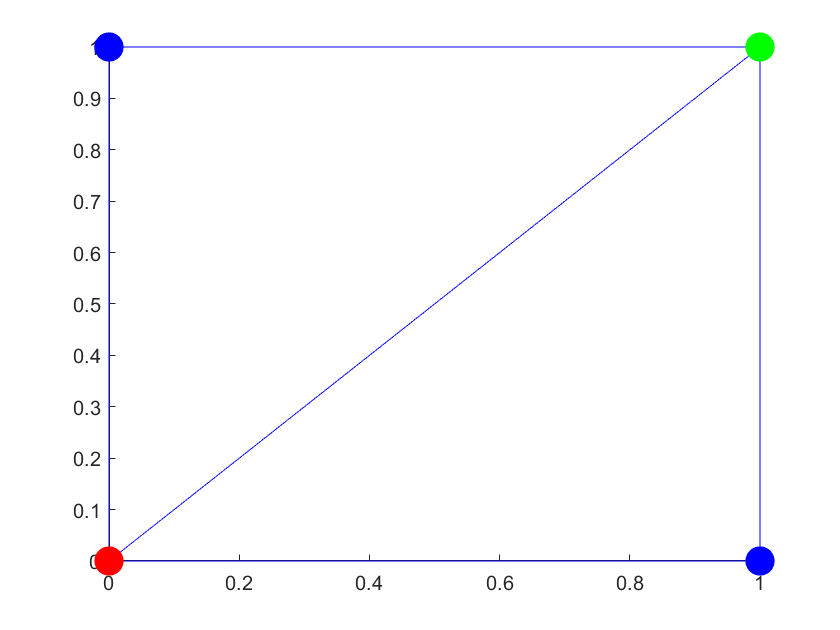

XY = [1,0;
      1,1;
      0,1;
      0,0];
hold on;
gplot(G,XY, '-ob');
for i = 1:n
    switch x(i)
        case red
            plot(XY(i,1), XY(i,2), '.r','MarkerSize',50);
        case green
            plot(XY(i,1), XY(i,2), '.g','MarkerSize',50);
        case blue
            plot(XY(i,1), XY(i,2), '.b','MarkerSize',50);
    end
end
hold off;